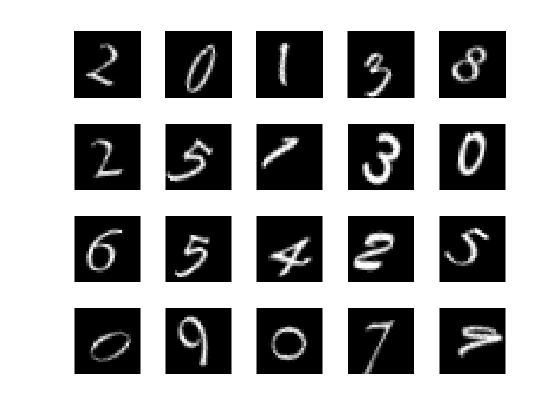

% imageDatastore automáticamente le pone labels a las imágenes basado en
% los nombres de los folders en los que está guardada la data. 

digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', 'nndatasets', 'DigitDataset');
imds = imageDatastore(digitDatasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Display algunas imágenes del data set

figure;
perm = randperm(10000, 20);          % Crea 20 números aleatorios de 0 a 10000
for i = 1:20
    subplot(4, 5, i);               % Una matriz de imágenes de 4 filas y 5 columnas
    imshow(imds.Files{perm(i)});
end

% Muestra todos los labels que existen en la database basando en el número
% de subfolders presentes en la base de datos

labelCount = countEachLabel(imds)

labelCount = 10×2 table
    Label    Count
    _____    _____

      0      1000 
      1      1000 
      2      1000 
      3      1000 
      4      1000 
      5      1000 
      6      1000 
      7      1000 
      8      1000 
      9      1000 


% Se obtiene el tamaño de las imágenes con las que se entrenará la red
% neuronal

size(readimage(imds,1))

ans =     28    28


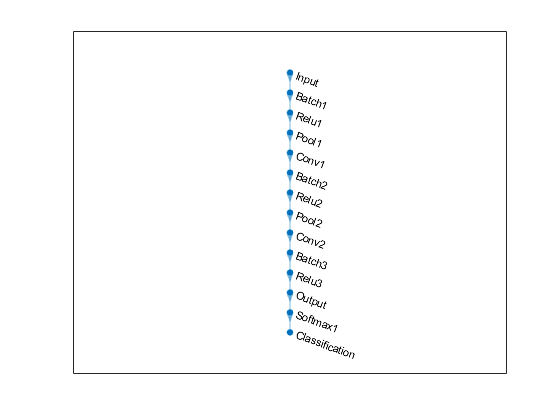

% Divide el dataset en "Training Data" y "Validation Data". En el ejemplo
% se utilizan 750 datos para entrenar y el resto para validar

numTrainFiles = 750;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, 'randomized');

% Definición de la arquitectura de la red neuronal a utilizar
layers = [
    imageInputLayer([28 28 1], 'Name', 'Input')     % Tamaño de la capa de entrada
    batchNormalizationLayer('Name', 'Batch1')       % Se normalizan los valores de entrada para incrementar rendimiento y hacer más efectivo al algoritmo
    reluLayer('Name', 'Relu1')                      % La batch normalization es seguida de una función de activación. La más común es la unidad lineal rectificada
    
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'Pool1')  % Se reduce la escala de la imagen al hacer que el programa tome una región de 2x2, saque el valor máx de cada canal y luego se mueva en incrementos de 2 pixeles en X y Y
    
    convolution2dLayer(3, 16, 'Padding', 'same','Name','Conv1')    % Capa convolucional con un filtro de 3x3 pixeles. 16 es el número de neuronas ne la capa. 
    batchNormalizationLayer('Name', 'Batch2')  
    reluLayer('Name', 'Relu2')  
    
    maxPooling2dLayer(2,'Stride', 2, 'Name', 'Pool2');   % Otro downsampling
    
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'Conv2')
    batchNormalizationLayer('Name', 'Batch3')
    reluLayer('Name', 'Relu3')
    
    fullyConnectedLayer(10,'Name','Output')             % Luego del downsampling, se coloca una capa conectada completamente con 10 salidas, una por cada dígito.
    softmaxLayer('Name','Softmax1')                     % Función que normaliza la salida de la capa de output. Esta retorna números positivos cuya suma llega a 1
    classificationLayer('Name', 'Classification')];     % Esta capa obtiene el porcentaje más alto calculado para el input y retorna una salida mutuamente exclusiva o una única salida de las 10 posibles.

lgraph = layerGraph(layers);
figure
plot(lgraph);


% Opciones de entrenamiento

options = trainingOptions('sgdm', ...   % Utilizar descenso gradiente estocástico con momento
    'InitialLearnRate', 0.01, ...       % Con un learning rate inicial de 0.01 (Tasa a la que cambian los pesos de la red)
    'MaxEpochs', 4, ...                 % 4 ciclos de entrenamiento máximos
    'Shuffle', 'every-epoch', ...       % Los datos se reordenan luego de cada ciclo o epoch
    'ValidationData', imdsValidation, ...   % No se entrena a la red con la Validation Data
    'ValidationFrequency', 30, ...      % Valida la precisión de la red cada 30 iteraciones
    'Verbose', false, ...               % No muestra información adicional sobre el entrenamiento
    'Plots','training-progress');       % Plotear el progreso en el entrenamiento


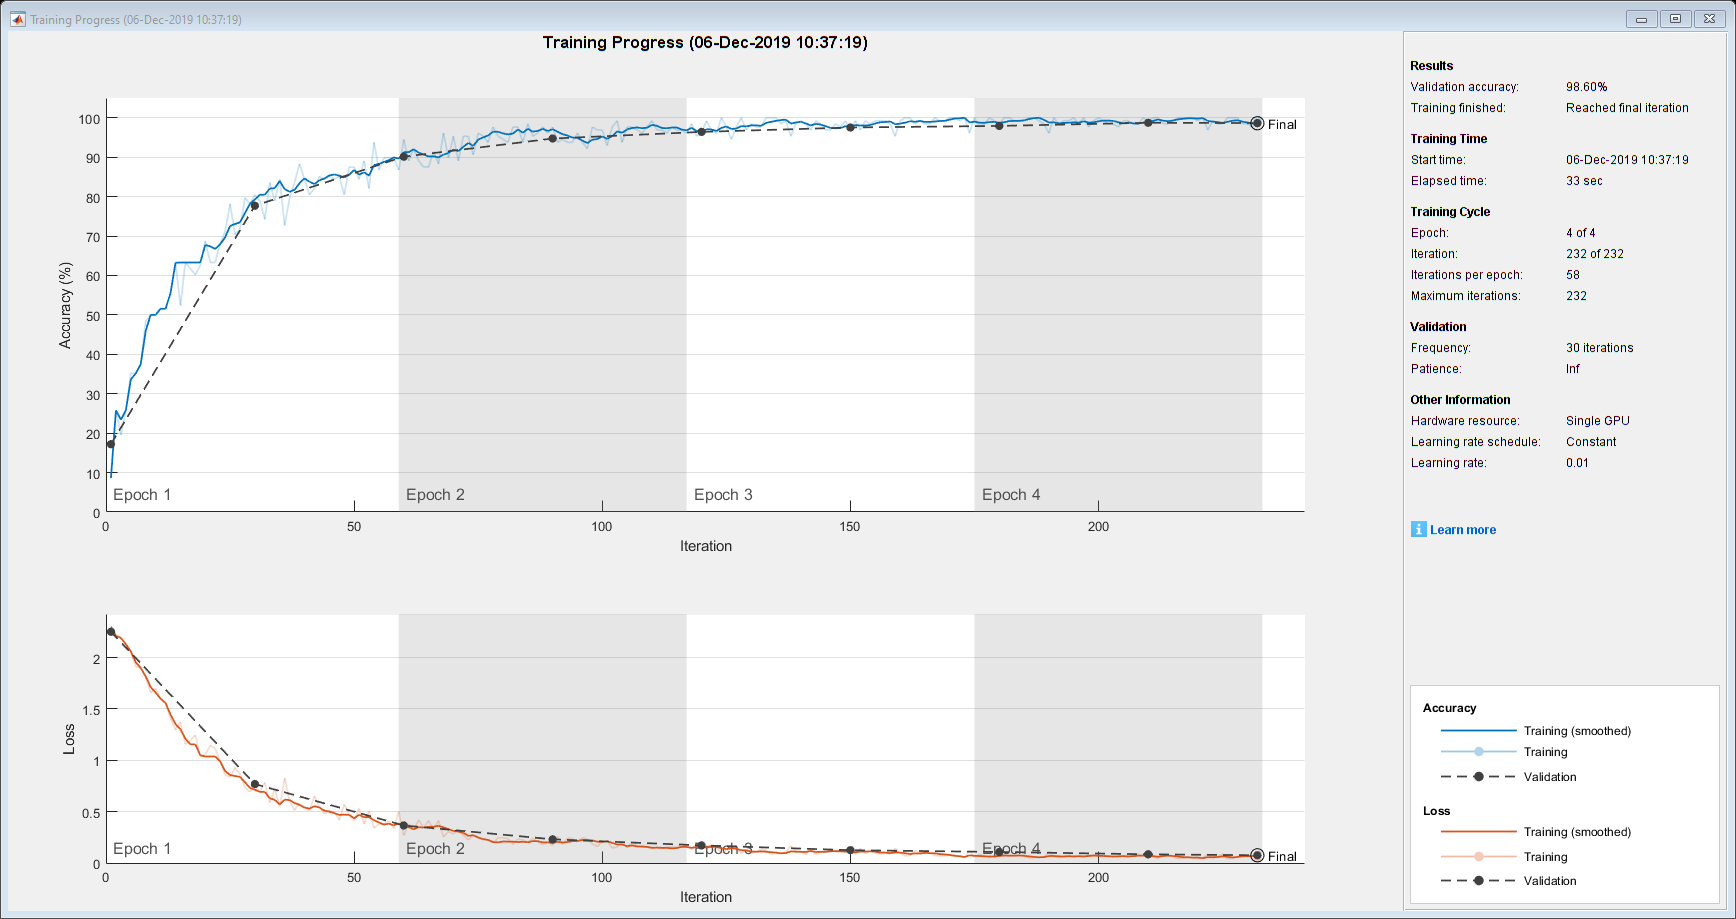

% Entrenamiento de la red neuronal utilizando los settings previamente
% colocados

net = trainNetwork(imdsTrain, layers, options);

% Predecir las labels de la data de validación
Muestra = randi([1 2500],1,1)

Muestra = 1239

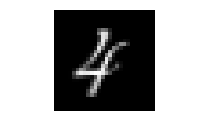


imshow(imdsValidation.Files{Muestra}, 'InitialMagnification', 'fit')

YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation);
Prediccion = YPred(Muestra)

Prediccion = categorical
     4 
